## 灰色预测

### 1.准指数规律检验

    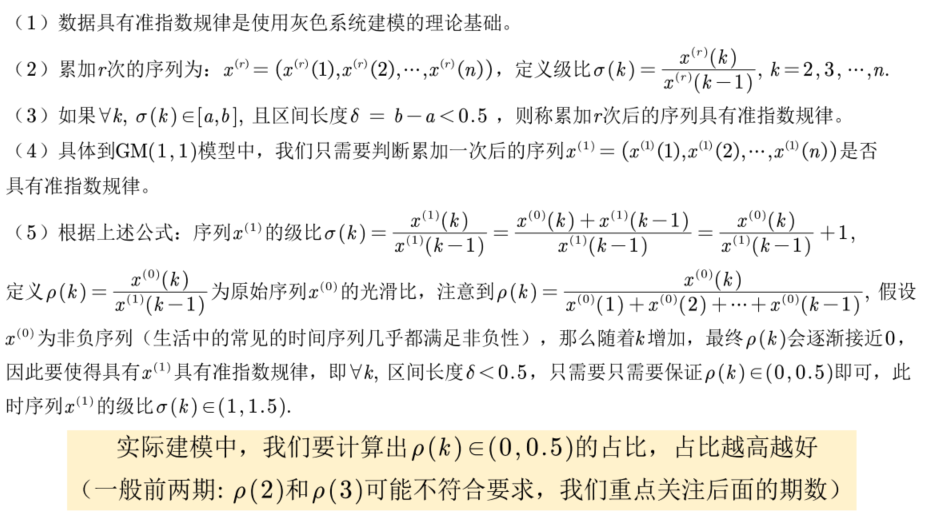 

### 2.程序思路

    1. 画出原始数据的时间序列图，并判断原始数据中是否有负数或期数是否低于4期，如果是的话则报错，否则执行下一步；

    2. 对一次累加后的数据进行准指数规律检验，返回两个指标：

    指标1：光滑比小于0.5的数据占比（一般要大于60%）

    指标2：除去前两个时期外，光滑比小于0.5的数据占比（一般大于90%）

    3.1 数据期数为4：

    分别计算出传统的GM(1,1)模型、新信息GM(1,1)模型和新陈代谢GM(1,1)模型对于未来期数的预测结果，为了保证结果的稳健性，对三个结果求平均值作为预测值。

    3.2 数据期数为5,6或7：

    取最后两期为试验组，前面的n‐2期为训练组；用训练组的数据分别训练三种GM模型，并将训练出来的模型分别用于预测试验组的两期数据；利用试验组两期的真实数据和预测出来的两期数据，可分别计算出三个模型的SSE；选择SSE最小的模型作为我们建模的模型。

    3.3 数据期数大于7：

    取最后三期为试验组，其他的过程和4.2类似。

    4. 输出并绘制图形显示预测结果，并进行残差检验和级比偏差检验。

### 3.注意事项

    1.本程序在进行准指数规律检验后，默认检验同通过，所以还需根据输出的两个指标自行判断

    2.本程序只需更改 year、data、data_predict_num 三种数据即可

    3.发展系数越小越好

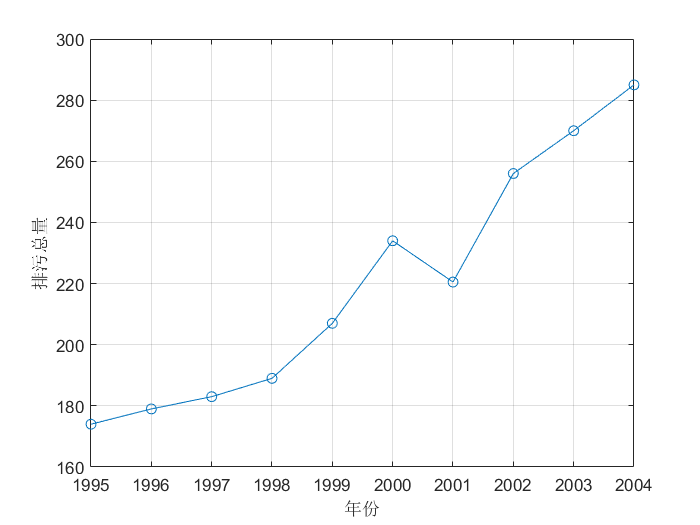

%   灰色预测
%   本程序只需更改 year、data、data_predict_num 三种数据即可
%   本程序在进行准指数规律检验后，默认检验同通过，所以还需根据输出的两个指标自行判断
clc
clear

year = [1995 : 1 : 2004]';  % 年份
data = [174, 179, 183, 189, 207, 234, 220.5, 256, 270, 285]'; % 原始数据
data_predict_num = 3;  % 预测期数

%---绘制原始数据的时间序列图---%
figure(1)  % 设置图形编号
plot(year, data, 'o-');  % 原式数据的时间序列图
grid on;  % 显示网络格
set(gca, 'xtick', year(1 : 1 : end))  % 设置 x 轴横坐标的间隔为 1
xlabel('年份');
ylabel('排污总量');

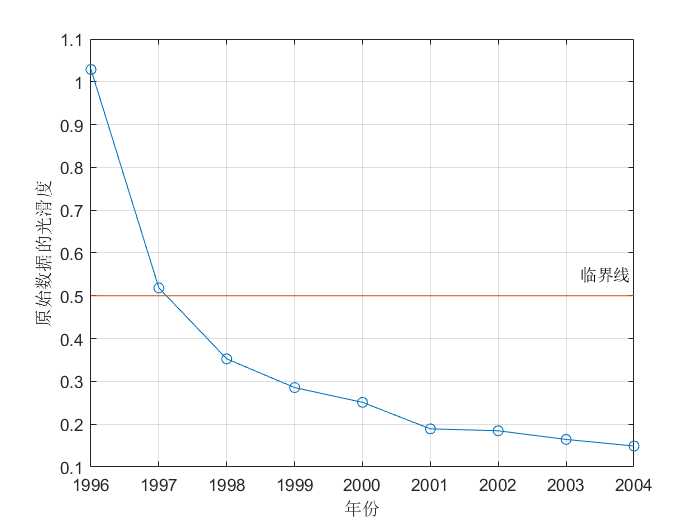

-------------------------------------------


指标1：光滑度小于 0.5 的数据占比为：77.8%  
一般需大于60%

指标2：除去前两个时期外，光滑比小于 0.5 的数据占比为：100.0%  
一般需大于90%

-------------------------------------------


元数据大于 4，可将数据分为训练组和试验组


传统的 GM(1, 1) 模型预测


发展系数为：0.053355
灰作用量为：162.135787



新信息 GM(1, 1) 模型预测


发展系数为：0.053355
灰作用量为：162.135787

发展系数为：0.053316
灰作用量为：162.158866

发展系数为：0.053284
灰作用量为：162.180566



新陈代谢的 GM(1, 1) 模型预测


发展系数为：0.053355
灰作用量为：162.135787

发展系数为：0.055735
灰作用量为：169.078690

发展系数为：0.054739
灰作用量为：180.053794



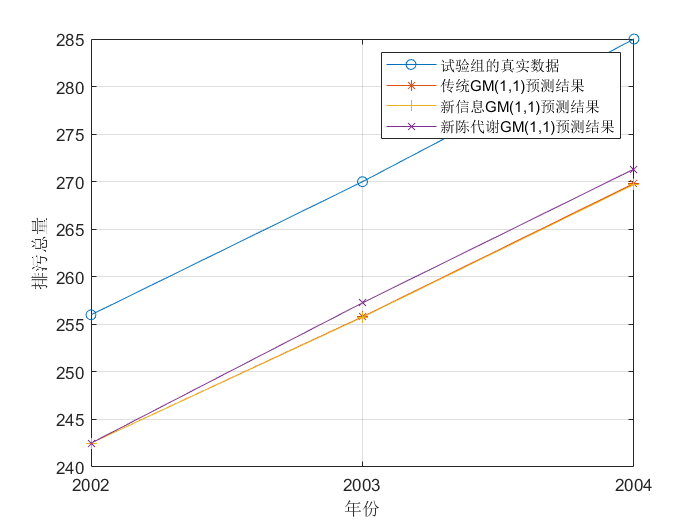

误差平方和


传统：614.061206


新信息：618.962202


新陈代谢：531.154827


使用新陈代谢的GM(1,1)进行预测！


发展系数为：0.062398
灰作用量为：156.616175



发展系数为：0.062398
灰作用量为：156.616175

发展系数为：0.064197
灰作用量为：164.723191

发展系数为：0.064416
灰作用量为：175.828073



对原始数据的拟合结果：


1995 ：174
1996 ：172.809
1997 ：183.9355
1998 ：195.7785
1999 ：208.3839
2000 ：221.801
2001 ：236.082
2002 ：251.2825
2003 ：267.4616
2004 ：284.6825


往后预测3期的得到的结果：


2005 ：303.0122
2006 ：324.3254
2007 ：346.0304


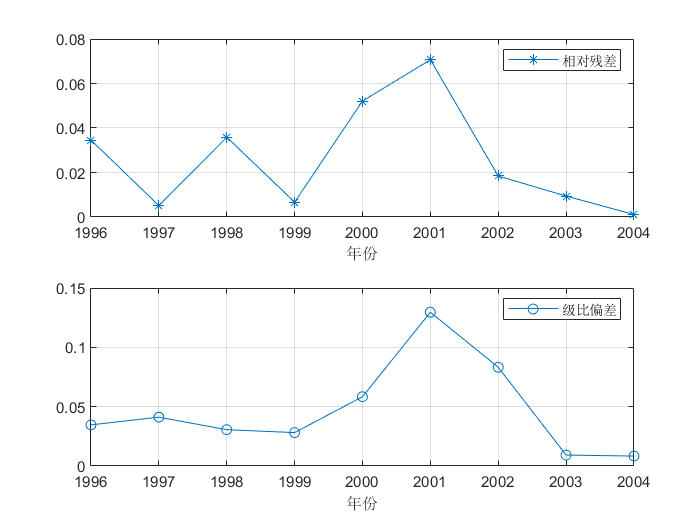

平均相对残差为：0.025999


残差检验的结果表明：该模型对原数据的拟合程度非常不错


平均级比偏差为：0.047041


该模型对原数据的拟合程度非常不错


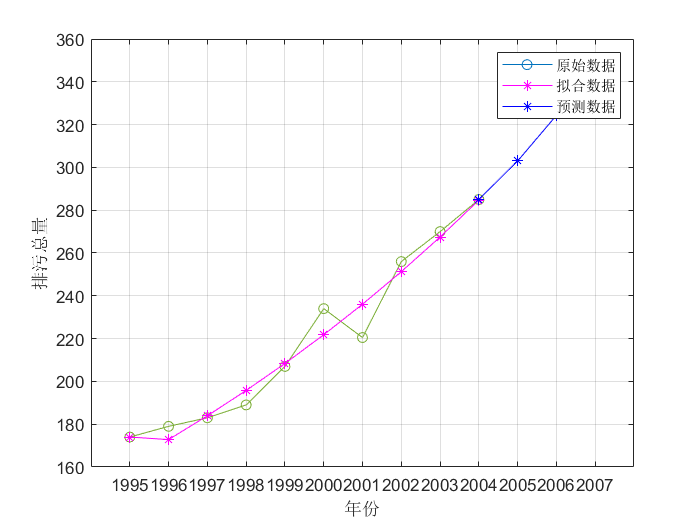



%---检验数据---%
err_flag = 0;

% 判断是否有负数
if sum(data < 0) > 0
    err_flag = 1;
    disp('时间序列（x轴）数据错误！')
end

% 判断数据量是否太少
data_len = length(data);
if data_len < 4
    err_flag = 2;
    disp('数据量太少，灰色预测误差太大！')
    disp(strcat('原始数据的长度为', num2str(data_len))) 
elseif data_len > 10
    disp('数据量较多，可以考虑使用其他方法！如 ARIMA, 指数平滑')
end


if err_flag == 0
    
    %---准指数规律检验---%
    data_ago = cumsum(data); % 生成 1-AGO 序列（累加）
    data_rho = data(2 : end) ./ data_ago(1 : end - 1);  % 计算光滑度

    % 画出光滑度图形
    figure(2)
    plot(year(2 : end), data_rho, 'o-', [year(2), year(end)], [0.5, 0.5], '-'); 
    grid on;
    text(year(end - 1) + 0.2, 0.55, '临界线')   % 在坐标(year(end-1)+0.2,0.55)上添加文本
    set(gca, 'xtick', year(2 : 1 : end))  % 设置 x 轴横坐标的间隔为1
    xlabel('年份');  
    ylabel('原始数据的光滑度');  % 给坐标轴加上标签
    
    % 输出两个指标
    disp('-------------------------------------------')
    fprintf("指标1：光滑度小于 0.5 的数据占比为：%.1f%%  \n一般需大于60%%", 100 * sum(data_rho < 0.5) / (data_len - 1));
    fprintf("指标2：除去前两个时期外，光滑比小于 0.5 的数据占比为：%.1f%%  \n一般需大于90%%", 100 * sum(data_rho(3 : end) < 0.5) / (data_len-3));
    disp('-------------------------------------------')
    
    if data_len > 4
        disp('元数据大于 4，可将数据分为训练组和试验组')
        
        % 决定试验组的数量
        if data_len > 7
            data_test_num = 3; 
        else
            data_test_num = 2;
        end
        data_train = data(1 : end - data_test_num);  % 训练数据
        data_test = data(end - data_test_num + 1 : end);
        
        % 使用三种模型对训练数据进行训练
        disp('传统的 GM(1, 1) 模型预测')
        data_gm11 = gm11(data_train, data_test_num);  % 使用传统的 GM(1, 1)
        
        disp('新信息 GM(1, 1) 模型预测')
        data_gm11_new = gm11_new(data_train, data_test_num);  % 使用新信息 GM(1, 1)
        
        disp('新陈代谢的 GM(1, 1) 模型预测')
        data_gm11_new2 = gm11_new2(data_train, data_test_num);  % 使用新陈代谢 GM(1, 1)
        
        % 比较三种模型对于训练数据的结果，判断哪种模型效果最好
        test_year = year(end - data_test_num + 1 : end);  % 试验组对应的年份
        
        figure(3)
        plot(test_year, data_test, 'o-', ...
             test_year, data_gm11, '*-', ...
             test_year, data_gm11_new, '+-', ...
             test_year, data_gm11_new2, 'x-'); 
        grid on;
        set(gca, 'xtick', year(end - data_test_num + 1) : 1 : year(end))  % 设置x轴横坐标的间隔为1
        legend('试验组的真实数据', '传统GM(1,1)预测结果', '新信息GM(1,1)预测结果', '新陈代谢GM(1,1)预测结果')  % 注意：如果lengend挡着了图形中的直线，那么lengend的位置可以自己手动拖动
        xlabel('年份');  
        ylabel('排污总量');
        
        % 计算误差平方，并选出误差最小的方法
        sse_gm11 = sum((data_test - data_gm11) .^ 2);
        sse_gm11_new = sum((data_test - data_gm11_new) .^ 2);
        sse_gm11_new2 = sum((data_test - data_gm11_new2) .^ 2);
        
        fprintf("误差平方和\n")
        fprintf("传统：%f\n", sse_gm11)
        fprintf("新信息：%f\n", sse_gm11_new)
        fprintf("新陈代谢：%f\n", sse_gm11_new2)
        
        if sse_gm11 <= sse_gm11_new2  && sse_gm11 <= sse_gm11_new
            see_flag = 1;
            disp('使用传统的GM(1,1)进行预测！')
        elseif sse_gm11_new <=  sse_gm11 && sse_gm11_new <= sse_gm11_new2
            see_flag = 2;
            disp('使用新信息的GM(1,1)进行预测！')
        elseif sse_gm11_new2 <= sse_gm11 && sse_gm11_new2 <= sse_gm11_new
            see_flag = 3;
            disp('使用新陈代谢的GM(1,1)进行预测！')
        end
        
        % 灰色预测
        [r, data_hat, r_res, data_eta] = gm11(data, data_predict_num);  % 使用 gm11 得到详细结果
        
        if see_flag == 2
            r = gm11_new(data, data_predict_num);
        elseif see_flag == 3
            r = gm11_new2(data, data_predict_num);
        end
        
        % 输出结果
        disp('对原始数据的拟合结果：')
        for i = 1 : data_len
            disp(strcat(num2str(year(i)), ' ： ', num2str(data_hat(i))))
        end
        disp(strcat('往后预测', num2str(data_predict_num), '期的得到的结果：'))
        
        for i = 1 : data_predict_num
            disp(strcat(num2str(year(end) + i), ' ：', num2str(r(i))))
        end
    else
        disp('数据只有 4 期，将三种方法求平均')
        
        % 使用三种模型对训练数据进行训练
        disp('传统的 GM(1, 1) 模型预测')
        [data_gm11, data_hat, r_res, data_eta] = gm11(x0, predict_num);  % 使用传统的 GM(1, 1)
        
        disp('新信息 GM(1, 1) 模型预测')
        data_gm11_new = gm11_new(data, data_predict_num);  % 使用新信息 GM(1, 1)
        
        disp('新陈代谢的 GM(1, 1) 模型预测')
        data_gm11_new2 = gm11_new2(data, data_predict_num);  % 使用新陈代谢 GM(1, 1)
        
        % 求平均
        r = (data_gm11 + data_gm11_new + data_gm11_new2) / 3;  
        
        disp('对原始数据的拟合结果')
        for i = 1 : data_len
            disp(strcat(num2str(year(i)), '：', num2str(data_hat(i))))
        end
        disp(strcat('传统GM(1,1)往后预测',num2str(predict_num),'期的得到的结果：'))
        
        for i = 1 : data_predict_num
            disp(strcat(num2str(year(end)+i), '：',num2str(result1(i))))
        end
        disp(strcat('新信息GM(1,1)往后预测',num2str(predict_num),'期的得到的结果：'))
        
        for i = 1 : data_predict_num
            disp(strcat(num2str(year(end)+i), '：',num2str(result2(i))))
        end
        disp(strcat('新陈代谢GM(1,1)往后预测',num2str(predict_num),'期的得到的结果：'))
        
        for i = 1 : data_predict_num
            disp(strcat(num2str(year(end)+i), '：',num2str(result3(i))))
        end
        disp(strcat('三种方法求平均得到的往后预测',num2str(predict_num),'期的得到的结果：'))
        
        for i = 1 : data_predict_num
            disp(strcat(num2str(year(end)+i), '：',num2str(result(i))))
        end
    end
        
    % 绘制相对残差和级比偏差的图形
    figure(4)
    subplot(2, 1, 1)  % 绘制子图（将图分块）
    plot(year(2 : end), r_res, '*-');  % 原数据中的各时期和相对残差
    grid on;   
    legend('相对残差'); 
    xlabel('年份');
    set(gca, 'xtick', year(2 : 1 : end))  % 设置 x 轴横坐标的间隔为 1
    
    subplot(2, 1, 2)
    plot(year(2 : end), data_eta, 'o-'); 
    grid on;   % 原数据中的各时期和级比偏差
    legend('级比偏差'); 
    xlabel('年份');
    set(gca, 'xtick', year(2 : 1 : end))  % 设置 x 轴横坐标的间隔为 1    
    
    % 残差检验
    r_res_mean = mean(r_res);  % 计算平均相对残差
    fprintf("平均相对残差为：%f\n", r_res_mean)
    
    if r_res_mean < 0.1
        disp('残差检验的结果表明：该模型对原数据的拟合程度非常不错')
    elseif r_res_mean < 0.2
        disp('残差检验的结果表明：该模型对原数据的拟合程度达到一般要求')
    else
        disp('残差检验的结果表明：该模型对原数据的拟合程度不太好，建议使用其他模型预测')
    end
        
    % 级比偏差检验
    data_eta_mean = mean(data_eta);   % 计算平均级比偏差
    fprintf("平均级比偏差为：%f\n", data_eta_mean)
    
    if data_eta_mean < 0.1
        disp('该模型对原数据的拟合程度非常不错')
    elseif data_eta_mean < 0.2
        disp('该模型对原数据的拟合程度达到一般要求')
    else
        disp('该模型对原数据的拟合程度不太好，建议使用其他模型预测')
    end
    
    % 绘制预测图
    figure(5)  
    plot(year, data, '-o', ...
         year, data_hat,'-*m', ...
         year(end) + 1 : year(end) + data_predict_num, r,'-*b' );   
    grid on;
    hold on;
    plot([year(end), year(end) + 1], [data(end), r(1)], '-*b')
    legend('原始数据', '拟合数据', '预测数据')
    set(gca, 'xtick', [year(1) : 1 : year(end) + data_predict_num])  % 设置 x 轴间隔为 1
    xlabel('年份');  
    ylabel('排污总量');
end 